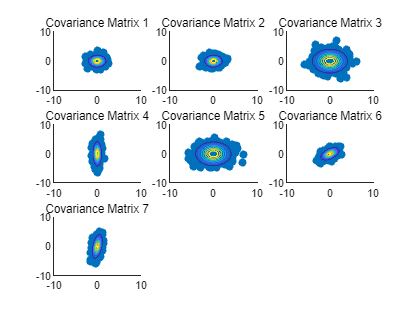

clear;clc;
% 生成二元正态分布样本
mu = [0,0]; % 均值向量
% 协方差矩阵
Sigma = cat(3, [1,0;0,1], [1,0;0,1], [4,0;0,4], ...
        [0.2,0;0,4], [4,0;0,4], [1,0.5;0.5,1], [0.3,0.5;0.5,4]);
[m,n,l]=size(Sigma);
% 循环每个协方差矩阵
for i = 1:l
    R = mvnrnd(mu, Sigma(:,:,i), 500); % 生成样本
    subplot(3, 3, i) % 创建子图
    scatter(R(:,1), R(:,2), 'filled'); % 散点图
    hold on;
    % 创建等高线
    x1 = min(R(:,1)):0.1:max(R(:,1));
    x2 = min(R(:,2)):0.1:max(R(:,2));
    [X1,X2] = meshgrid(x1,x2);
    F = mvnpdf([X1(:) X2(:)],mu,Sigma(:,:,i));
    F = reshape(F,length(x2),length(x1));
    contour(x1,x2,F);
    hold off;
    title(['Covariance Matrix ' num2str(i)]); % 添加标题
    xlim([-10, 10]) % x轴范围
    ylim([-10, 10]) % y轴范围
end

disp(Sigma);


(:,:,1) =

     1     0
     0     1


(:,:,2) =

     1     0
     0     1


(:,:,3) =

     4     0
     0     4


(:,:,4) =

    0.2000         0
         0    4.0000


(:,:,5) =

     4     0
     0     4


(:,:,6) =

    1.0000    0.5000
    0.5000    1.0000


(:,:,7) =

    0.3000    0.5000
    0.5000    4.0000

